# Nonlinear MPC

## Problem Formulation

% Initial Conditions
x0 = [0;0;0;0;0;0];

% Refernece
ref = [5; 0; 0; 0; 0; 0];

% Prediction Horizon
N = 30;

% Sampling Time
dt = 0.04;

% Number of Constraints
cn = 8;

## Part A

for i = 1:2
[n,m] = Hw5_Initialize(dt,ref,0,i);

Then, given an initial guess $\left(z^0 ,\lambda^0 \right)$

% Initial guess
z = zeros((n+m)*N,1);
l = zeros( n   *N,1); 

## NMPC Implementation without Constraints

% Solver Settings
imax = 4;
tol = 1e-2;

% Receding Horizon NMPC
T = 4;

xtt = zeros(n,T/dt);
ytt = zeros(1,T/dt);
utt = zeros(m,T/dt);
x = x0;
for tt = 1:T/dt
    
    % Solve NLP
    for iter = 1:imax
        
        % Generate sub-QP
        [H,h,E,e,C,c] = gen_QP(z,l,x,n,m,N,cn);
    
        % Solve sub-QP
        [dz,l] = solve_QP(H,h,E,e,C,c,0);
        
        % Update solution estimate
        z = z + dz;
        
        % Check residual
        % res = [H*z+E'*l ; e ]'*[H*z+E'*l ; e ];
        res = dz'*dz;
    
        if res <= tol
            % NLP Solved!
            break
        end
    
    end
    
    % Control Input
    u = z(1:m);
    
    % Save Data
    utt(:,tt) = u;
    xtt(:,tt) = x;
    ytt(:,tt) = x(5)-atan((x(2)+1.56*x(4))/30);
    
    % Update System
    x = f(x,u);

end

The plots of trajectory of the closed-loop system subject to a receding horizon NMPC (blue) with no terminal cost, and the NMPC (red) with terminal cost are shown below.  

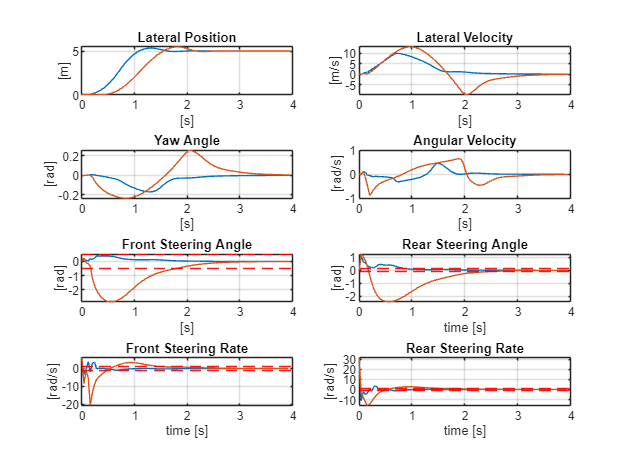

sys_plot(0:dt:T-dt,xtt,utt(:,1:end-1));
end

The NMPC with terminal cost (red line) demonstrates smoother and more stable control actions across the parameters evaluated, particularly noticeable in steering angles, however there is a steep drop in steering rate which is not desirable. Further, the inclusion of terminal cost helps in less aggressive, more predictive control nature of the system and enhaced safety.

Whereas, blue line with no terminal cost has more transient/vibrant behaviour which is nondesirable for physical system, but it does not have steep changes like NMPC with terminal cost. However, both nMPC with and without terminal cost violates the cvonstraints.

## NMPC Implementation with Constraints

We now implement our SQP solver over a receding horizon.

% Initial guess
z = zeros((n+m)*N,1);
l = zeros( n   *N,1); 

% Solver Settings
imax = 4;
tol = 1e-2;

% Receding Horizon NMPC
T = 3;

xtt = zeros(n,T/dt);
ytt = zeros(1,T/dt);
ytt1 = zeros(1,T/dt);
utt = zeros(m,T/dt);
x = x0;
for tt = 1:T/dt
    
    % Solve NLP
    for iter = 1:imax
        
        % Generate sub-QP
        [H,h,E,e,C,c] = gen_QP(z,l,x,n,m,N,cn);
    
        % Solve sub-QP
        [dz,l] = solve_QP(H,h,E,e,C,c,1);
        
        % Update solution estimate
        z = z + dz;
        
        % Check residual
        % res = [H*z+E'*l ; e ]'*[H*z+E'*l ; e ];
        res = dz'*dz;
    
        if res <= tol
            % NLP Solved!
            break
        end
    
    end
    
    % Control Input
    u = z(1:m);
    
    % Save Data
    utt(:,tt) = u;
    xtt(:,tt) = x;
    ytt(:,tt) = x(5)-atan((x(2)+1.56*x(4))/30);
    ytt1(:,tt) = x(6)-atan((x(2)-1.64*x(4))/30);
    
    % Update System
    x = f(x,u);

end

We now plot the trajectory of the closed-loop system subject to a receding horizon NMPC (blue), as well as the initial NLP solution at time $t=0$ (red)  

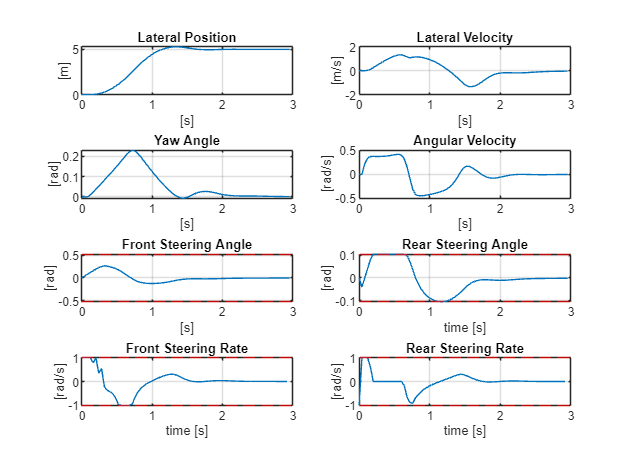

figure
sys_plot(0:dt:T-dt,xtt,utt(:,1:end-1));

From the above plots we can see that the system does not violates any constraints, this is the result of sufficient prediction horizon. Note that there is no addition of terminal cost because perdiction horizon itself satisfies the system constraints.

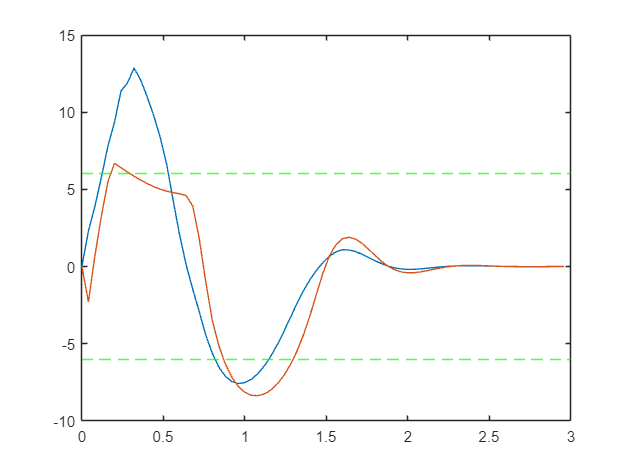

figure
plot(0:dt:T-dt,rad2deg(ytt)); hold on
plot(0:dt:T-dt,rad2deg(ytt1));
yline(6,'--g')
yline(-6,'--g')

Due to not enforcing the steering constraints both del_f and del_r are been violated.

## NMPC Implementation with Constraints on sideslip angles

We now implement our SQP solver over a receding horizon.

cn = 12;

[n,m] = Hw5_Initialize(dt,ref,1,2);

% Initial guess
z = zeros((n+m)*N,1);
l = zeros( n   *N,1); 

% Solver Settings
imax = 4;
tol = 1e-2;

% Receding Horizon NMPC
T = 3;

xtt = zeros(n,T/dt);
ytt = zeros(1,T/dt);
ytt1 = zeros(1,T/dt);
utt = zeros(m,T/dt);
x = x0;
for tt = 1:T/dt
    
    % Solve NLP
    for iter = 1:imax
        
        % Generate sub-QP
        [H,h,E,e,C,c] = gen_QP(z,l,x,n,m,N,cn);
    
        % Solve sub-QP
        [dz,l] = solve_QP(H,h,E,e,C,c,1);
        
        % Update solution estimate
        z = z + dz;
        
        % Check residual
        % res = [H*z+E'*l ; e ]'*[H*z+E'*l ; e ];
        res = dz'*dz;
    
        if res <= tol
            % NLP Solved!
            break
        end
    
    end
    
    % Control Input
    u = z(1:m);
    
    % Save Data
    utt(:,tt) = u;
    xtt(:,tt) = x;
    ytt(:,tt) = x(5)-atan((x(2)+1.56*x(4))/30);
    ytt1(:,tt) = x(6)-atan((x(2)-1.64*x(4))/30);
    
    % Update System
    x = f(x,u);

end

We now plot the trajectory of the closed-loop system subject to a receding horizon NMPC (blue), as well as the initial NLP solution at time $t=0$ (red)  

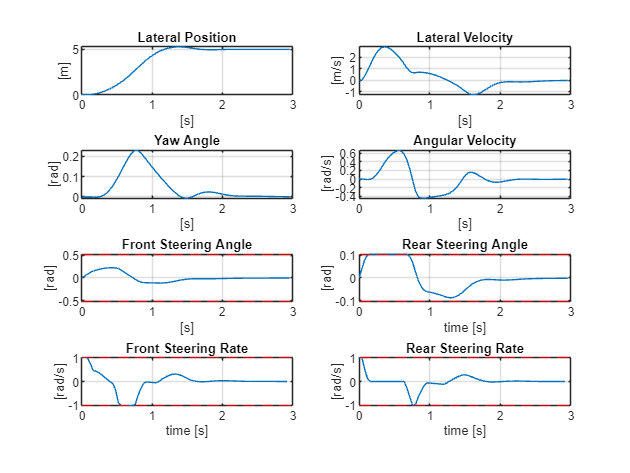

figure
sys_plot(0:dt:T-dt,xtt,utt(:,1:end-1));

We can see that after enforcing sideslip constraints the system has smooth transition unlike the system with no terminal cost and reciding horizon. The system also does not violates any constraints as a result of long enough prediction horizon.

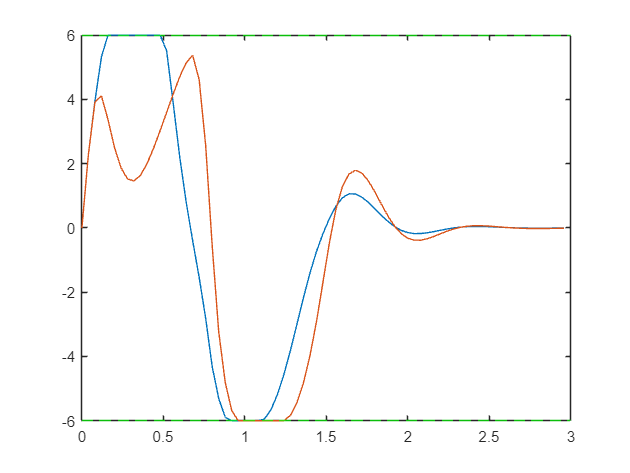

figure
plot(0:dt:T-dt,rad2deg(ytt)); hold on
plot(0:dt:T-dt,rad2deg(ytt1));
yline(6,'--g')
yline(-6,'--g')

Here the steering angles of the system are smooth and follows the constraints.

# Auxiliary Functions

function sys_plot(t,X,U)
% Create one figure with eight subplots
subplot(4,2,1)
plot(t,X(1,:))
ylabel('[m]')
xlabel('[s]')
title('Lateral Position')
grid on
hold on

subplot(4,2,2)
plot(t,X(2,:))
ylabel('[m/s]')
xlabel('[s]')
title('Lateral Velocity')
grid on
hold on

subplot(4,2,3)
plot(t,X(3,:))
ylabel('[rad]')
xlabel('[s]')
title('Yaw Angle')
grid on
hold on

subplot(4,2,4)
plot(t,X(4,:))
ylabel('[rad/s]')
xlabel('[s]')
title('Angular Velocity')
grid on
hold on

subplot(4,2,5)
plot(t,X(5,:))
ylabel('[rad]')
xlabel('[s]')
title('Front Steering Angle')
yline(deg2rad(30),'--r')
yline(deg2rad(-30),'--r')
grid on
hold on

subplot(4,2,6)
plot(t,X(6,:))
ylabel('[rad]')
xlabel('time [s]')
title('Rear Steering Angle')
yline(deg2rad(6),'--r')
yline(deg2rad(-6),'--r')
grid on
hold on

% figure
subplot(4,2,7)
plot(t(1:end-1),U(1,:))
ylabel('[rad/s]')
xlabel('time [s]')
title('Front Steering Rate')
yline(1,'--r')
yline(-1,'--r')
grid on
hold on

subplot(4,2,8)
plot(t(1:end-1),U(2,:))
ylabel('[rad/s]')
xlabel('time [s]')
title('Rear Steering Rate')
yline(1,'--r')
yline(-1,'--r')
grid on
hold on
end